## IED-TW delay VS  IED-LC delay

clc; close all; clear; addpath z_toolbox; 
addpath E:\IEDpropagation\z_toolbox\Violinplot;
load(fullfile('step3_IEDtravelingWave', 'IEDtw_meth-None_TD-6d0.mat'));
% Load IED cross-correlation data with polynomial fitting
load(fullfile('step5_IEDxcorr_polyfit', 'IED6d0_xcorr100ms_Rmax_delay_allSubject.mat'));
nS = 13; subID = 'sub-0014';
%% Extract IED transfer matrix
% Extract traveling wave delay matrix and transfer rate matrix
IEDtwD = IEDtw(nS).indirectTransferDelayMatrix;
IEDtwRate = IEDtw(nS).indirectTransferRateMatrix;
% Extract cross-correlation delay and correlation coefficient matrices
IEDxcD = Delay_allSubject{nS};
IEDxcR = xcR_allSubject{nS};
Mask = IEDtwRate;
Mask = Mask - diag(diag(Mask));
Mask(isnan(Mask)) = 0;
Mask(Mask<0.1) = 0;
zThd = 0.5 * log((1 + 0.3) ./ (1 - 0.3));
Mask(isnan(IEDxcR) | isinf(IEDxcR) | IEDxcR <= zThd) = 0;
Mask(isnan(IEDxcD) | isinf(IEDxcD)) = 0;
% Extract valid data points using the mask
IEDtwD = IEDtwD(Mask>0);
IEDxcD = IEDxcD(Mask>0);
x = IEDtwD; y = IEDxcD;
[r, p] = corr(x, y, "type", "Spearman");
disp(r); disp(p);

    0.6254

     0



figure('Units', 'centimeters', 'Position', [5, 5, 39, 33]);
subplot(3, 2, 1);
f_densityScatter(x, y, 4); 
hold on;
[~, Curve, ~] = f_polyfit(x, y, 1);
plot(Curve.x, Curve.y, 'r-', 'LineWidth', 2); 
hold off;
xlim([min(x), max(x)]);
ylim([min(y), max(y)]);
xlabel('IED-TW Delay (ms)'); 
ylabel('IED-LC Delay (ms)');
set(gca, 'box', 'off', 'FontName', 'Arial', 'FontSize', 16, 'LineWidth', 2);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
clc; clear;
load(fullfile('step5_IEDxcorr_polyfit', ...
    'IED6d0_XC100ms_polyfit_delays_Rmax_ED_es.mat'), ...
    'R_twxcD_rED', 'R_twxcD', 'P_twxcD_rED', 'P_twxcD');
disp(mean(R_twxcD)); disp(std(R_twxcD)); 

    0.6259

    0.1278



disp(mean(R_twxcD_rED(:, 6))); disp(std(R_twxcD_rED(:, 6)));

    0.5585

    0.1277



P_twxcD = P_twxcD*length(P_twxcD); 
P_twxcD_rED = P_twxcD_rED(:, 6)*size(P_twxcD_rED, 1);
if max(P_twxcD)<0.05; disp('sigificant'); end

sigificant


if max(P_twxcD_rED)<0.05; disp('sigificant'); end

sigificant


for nS = 1:length(R_twxcD)
    Rstr{nS} = 'Raw';
    Rstr{47+nS} = 'Partial';
end
R(1:47) = R_twxcD; R(48:47*2) = R_twxcD_rED(:, 6);
subplot(3, 2, 2);
vs = violinplot(R, Rstr, 'QuartileStyle','shadow', ...
    'Width', 0.2, 'GroupOrder', {'Raw', 'Partial'}, ...
    'ShowMean', true, 'ViolinAlpha', 0.5, ...
    'ViolinColor', [1, 0.6, 0.2; 0.8, 0.3, 0.05], ...
    'MarkerSize', 16);
ylabel('Spearman Correlation');
xlim([0.5, 2.5]); ylim([0.2, 0.95]);
set(gca, 'box', 'off', 'FontName', 'Arial', 'FontSize', 16, 'LineWidth', 2);

## Euclidean Distance VS IED-LC Delay

clc; clear; 
load(fullfile('step3_IEDtravelingWave', 'IEDtw_meth-None_TD-6d0.mat'));
% Load IED cross-correlation data with polynomial fitting
load(fullfile('step5_IEDxcorr_polyfit',  'IED6d0_xcorr100ms_Rmax_delay_allSubject.mat'));
% Process each subject individually
nS = 13; subID = 'sub-0014';
% Load Euclidean distance matrix
load(fullfile('step2_channelDistance',  [subID, '_EuclideabDistanceMatrix.mat']));
%% Extract IED transfer matrix
% Extract traveling wave delay matrix and transfer rate matrix
IEDtwRate = IEDtw(nS).indirectTransferRateMatrix;
% Extract cross-correlation delay and correlation coefficient matrices
IEDxcD = Delay_allSubject{nS};
IEDxcR = xcR_allSubject{nS};
Mask = IEDtwRate;
Mask = Mask - diag(diag(Mask));
Mask(isnan(Mask)) = 0;
Mask(Mask<0.1) = 0;
zThd = 0.5 * log((1 + 0.3) ./ (1 - 0.3));
Mask(isnan(IEDxcR) | isinf(IEDxcR) | IEDxcR <= zThd) = 0;
Mask(isnan(IEDxcD) | isinf(IEDxcD)) = 0;
% Extract valid data points using the mask
ED = DistanceWorld(Mask>0);
IEDxcD = IEDxcD(Mask>0);
x = ED; y = IEDxcD;
% Fit polynomial model to remove distance effect from IED cross-correlation delays
[polyModel, Curve, Ftest] = f_polyfit(x, y, 6);
disp(polyModel.adjR2); disp(Ftest.Fstat); disp(Ftest.p_value);

    0.6166

   1.5242e+03

     0



subplot(3, 3, 4);
f_densityScatter(x, y, 2); hold on;
plot(Curve.x, Curve.y, 'r-', 'LineWidth', 2); hold off;
xlim([min(x), max(x)]); ylim([min(y), max(y)]);
xlabel('Euclidean Distance (mm)'); ylabel('IED-LC Delay (ms)');
set(gca, 'box', 'off', 'FontName', 'Arial', 'FontSize', 16, 'LineWidth', 2);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
clc; clear;
load(fullfile('step5_IEDxcorr_polyfit', ...
    'IED6d0_XC100ms_polyfit_delays_Rmax_ED_es.mat'), ...
    'adjR2_xcDED', 'p_adjR2_xcDED');
x = adjR2_xcDED(:, 6);
p = p_adjR2_xcDED(:, 6)*size(p_adjR2_xcDED, 1);
disp(mean(x)); disp(std(x));

    0.4788

    0.1609



if max(p)<0.05; disp('significant'); end

significant


for nS = 1:length(x)
    adjR2str{nS} = 'ED vs. IED-LC Delay';
end
subplot(3, 3, 7);
vs = violinplot(x, adjR2str, 'QuartileStyle','shadow', ...
    'Width', 0.2, ...
    'ShowMean', true, 'ViolinAlpha', 0.5, ...
    'ViolinColor', [0, 0.3, 0.2], ...
    'MarkerSize', 16);
ylabel('Adjusted R^2');
xlim([0.5, 1.5]); ylim([0.1, 0.9]);
set(gca, 'box', 'off', 'FontName', 'Arial', 'FontSize', 16, 'LineWidth', 2);

## IED Lag FC VS IED LC-Delay

clc; clear; 
load(fullfile('step3_IEDtravelingWave', 'IEDtw_meth-None_TD-6d0.mat'));
% Load IED cross-correlation data with polynomial fitting
load(fullfile('step5_IEDxcorr_polyfit',  'IED6d0_xcorr100ms_Rmax_delay_allSubject.mat'));
% Process each subject individually
nS = 13; subID = 'sub-0014';
% Load Euclidean distance matrix
load(fullfile('step2_channelDistance',  [subID, '_EuclideabDistanceMatrix.mat']));
%% Extract IED transfer matrix
% Extract traveling wave delay matrix and transfer rate matrix
IEDtwRate = IEDtw(nS).indirectTransferRateMatrix;
% Extract cross-correlation delay and correlation coefficient matrices
IEDxcD = Delay_allSubject{nS};
IEDxcR = xcR_allSubject{nS};
Mask = IEDtwRate;
Mask = Mask - diag(diag(Mask));
Mask(isnan(Mask)) = 0;
Mask(Mask<0.1) = 0;
zThd = 0.5 * log((1 + 0.3) ./ (1 - 0.3));
Mask(isnan(IEDxcR) | isinf(IEDxcR) | IEDxcR <= zThd) = 0;
Mask(isnan(IEDxcD) | isinf(IEDxcD)) = 0;
% Extract valid data points using the mask
ED = DistanceWorld(Mask>0);
IEDxcD = IEDxcD(Mask>0);
IEDxcR = log(IEDxcR(Mask>0));
x = IEDxcR; y = IEDxcD;
[r, p] = corr(x, y, 'Type', 'Spearman');
disp(r); disp(p);

   -0.4844

     0



[~, Curve, ~] = f_polyfit(x, y, 1);
subplot(3, 3, 5);
f_densityScatter(x, y, 2); hold on;
plot(Curve.x, Curve.y, 'r-', 'LineWidth', 2); hold off;
xlim([min(x), max(x)]); ylim([min(y), max(y)]);
xlabel('log(IED Lag FC)'); ylabel('IED-LC Delay (ms)');
set(gca, 'box', 'off', 'FontName', 'Arial', 'FontSize', 16, 'LineWidth', 2);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
clc; clear;
load(fullfile('step5_IEDxcorr_polyfit', 'IED6d0_XC100ms_polyfit_delays_Rmax_ED_es.mat'), ...
    'R_xcDR', 'R_xcDR_rED', 'P_xcDR', 'P_xcDR_rED');
x = R_xcDR(:); y = R_xcDR_rED(:, 6);
disp(mean(x)); disp(std(x)); disp(mean(y)); disp(std(y));

   -0.5815

    0.1674

   -0.5353

    0.1743



P_xcDR = P_xcDR*length(P_xcDR);
P_xcDR_rED = P_xcDR_rED(:, 6)*size(P_xcDR_rED, 1);
if max(P_xcDR)<0.05; disp('sigificant'); end

sigificant


if max(P_xcDR_rED)<0.05; disp('sigificant'); end

sigificant


Rstr = {}; R = [];
for nS = 1:length(R_xcDR)
    Rstr{nS} = 'Raw';
    Rstr{47+nS} = 'Partial';
end
R(1:47) = x; R(48:47*2) = y;
subplot(3, 3, 8);
vs = violinplot(R, Rstr, 'QuartileStyle','shadow', ...
    'Width', 0.2, 'GroupOrder', {'Raw', 'Partial'}, ...
    'ShowMean', true, 'ViolinAlpha', 0.5, ...
    'ViolinColor', [0, 0.3, 0.2; 0.2, 0.8, 0.8], ...
    'MarkerSize', 16);
ylabel('Spearman Correlation');
xlim([0.5, 2.5]); ylim([-0.96, -0.2]);
set(gca, 'box', 'off', 'FontName', 'Arial', 'FontSize', 16, 'LineWidth', 2);

## SC Strength VS IED-LC Delay

clc; clear;
load(fullfile('step2_fiberTrack', ...
    'FiberMatrix_ncount_length_qa_allsubject.mat'), 'fiberCount');
% Load IED cross-correlation data
load(fullfile('step5_IEDxcorr_polyfit',...
    'IED6d0_xcorr100ms_Rmax_delay_allSubject.mat'), ...
    'Delay_allSubject', 'xcR_allSubject');
%% Process each subject
nS = 13; subID = 'sub-0014';
% Load inter-channel Euclidean distance matrix
load(fullfile('step2_channelDistance', [subID, '_EuclideabDistanceMatrix.mat']), 'DistanceWorld');
% Extract subject-specific data
IEDxcD = Delay_allSubject{nS};
IEDxcR = xcR_allSubject{nS};
fibN = fiberCount{nS};
% Extract valid data
Mask = IEDxcR;
Mask = Mask - diag(diag(Mask));
zThd = 0.5 * log((1 + 0.3) ./ (1 - 0.3));
Mask(isnan(IEDxcR) | isinf(IEDxcR) | IEDxcR <= zThd) = 0;
Mask(isnan(IEDxcD) | isinf(IEDxcD)) = 0;
Mask(fibN==0) = 0;
IEDxcD = IEDxcD(Mask>0);
fibN = log(fibN(Mask>0));
x = fibN; y = IEDxcD;
[r, p] = corr(x, y, "type", "Spearman");
disp(r); disp(p);

   -0.5312

   4.9199e-61



[~, Curve, ~] = f_polyfit(x, y, 1);
subplot(3, 3, 6);
f_densityScatter(x, y, 2); hold on;
plot(Curve.x, Curve.y, 'r-', 'LineWidth', 2); hold off;
xlim([min(x), max(x)]); ylim([min(y), max(y)]);
xlabel('SC Strength'); ylabel('IED-LC Delay (ms)');
set(gca, 'box', 'off', 'FontName', 'Arial', 'FontSize', 16, 'LineWidth', 2);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
clc; clear;
load(fullfile('step5_IEDxcorr_polyfit', 'IED6d0_XC100ms_polyfit_delay_fibN.mat'), ...
    'R_fibNxcD', 'R_fibNxcD_rED', 'P_fibNxcD', 'P_fibNxcD_rED');
idx = find(R_fibNxcD~=0);
R_fibNxcD = R_fibNxcD(idx);
R_fibNxcD_rED = R_fibNxcD_rED(idx);
P_fibNxcD = P_fibNxcD(idx);
P_fibNxcD = P_fibNxcD*length(P_fibNxcD);
P_fibNxcD_rED = P_fibNxcD_rED(idx);
P_fibNxcD_rED = P_fibNxcD_rED*length(P_fibNxcD_rED);
x = R_fibNxcD; y = R_fibNxcD_rED;
disp(mean(x)); disp(std(x)); disp(mean(y)); disp(std(y));

   -0.4215

    0.0999

   -0.0741

    0.0759



if max(P_fibNxcD)<0.05; disp('sigificant'); end

sigificant


if max(P_fibNxcD_rED)<0.05
    disp('sigificant');
else
    disp(length(find(P_fibNxcD_rED>0.05)));
end

    25



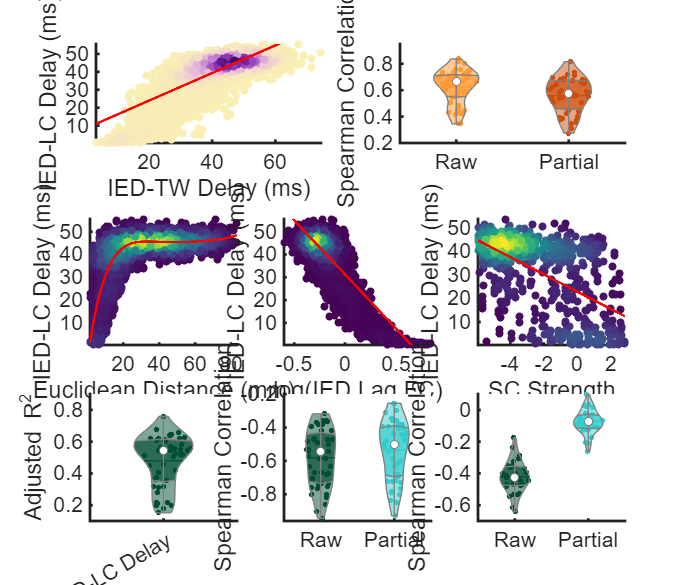

% violin plot
Rstr = {};
for nS = 1:length(R_fibNxcD)
    Rstr{nS} = 'Raw';
Rstr{33+nS} = 'Partial';
end
R = []; R(1:33) = x; R(34:33*2) = y;
subplot(3, 3, 9);
vs = violinplot(R, Rstr, 'QuartileStyle','shadow', ...
    'Width', 0.2, 'GroupOrder', {'Raw', 'Partial'}, ...
    'ViolinColor', [0, 0.3, 0.2; 0.2, 0.8, 0.8], ...
    'ShowMean', true, 'ViolinAlpha', 0.5, ...
    'MarkerSize', 16);
ylabel('Spearman Correlation');
xlim([0.5, 2.5]); ylim([-0.7, 0.1]);
set(gca, 'box', 'off', 'FontName', 'Arial', 'FontSize', 16, 'LineWidth', 2);